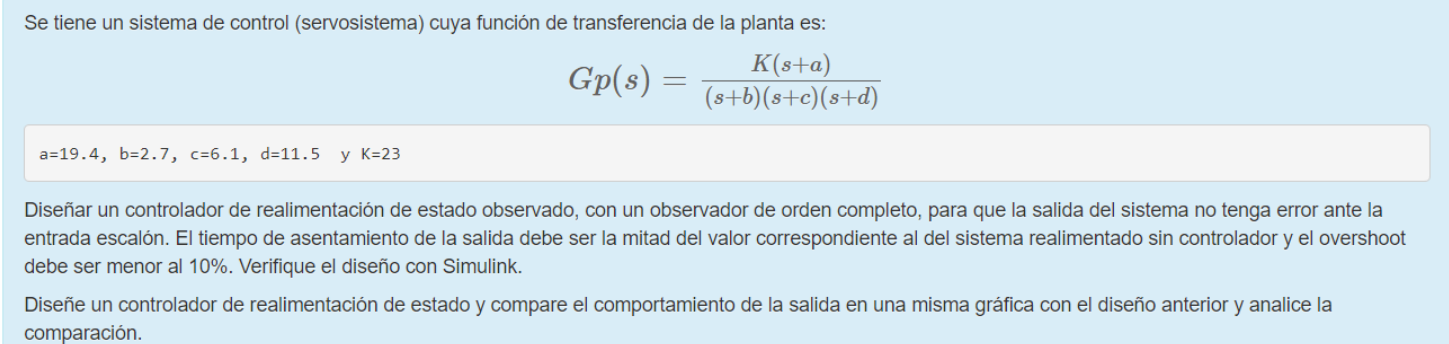

G=zpk([-0.9+i*0.995 -0.9-i*0.995],[-0.71 -3.7 -13.1],11)

G =
 
    11 (s^2 + 1.8s + 1.8)
  -------------------------
  (s+0.71) (s+3.7) (s+13.1)
 
Continuous-time zero/pole/gain model.



Gss=ss(G)

Gss =
 
  A = 
          x1     x2     x3
   x1  -0.71      1      0
   x2      0   -3.7  1.675
   x3      0      0  -13.1
 
  B = 
       u1
   x1   0
   x2   0
   x3   8
 
  C = 
           x1      x2      x3
   y1  0.8425  -2.143   1.375
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



stepinfo(feedback(G,1))

ans = struct with fields:
         RiseTime: 0.0594
    TransientTime: 3.8651
     SettlingTime: 3.8651
      SettlingMin: 0.2795
      SettlingMax: 0.3728
        Overshoot: 2.0874
       Undershoot: 0
             Peak: 0.3728
         PeakTime: 0.1303


ts=3.8651

ts = 3.8651

ts2=ts/2

ts2 = 1.9326

zita=-(log(0.1)/(sqrt(pi^2+(log(0.1))^2)))  %Para 10% de OV

zita = 0.5912

wn=4/(zita*(ts2))

wn = 3.5013

pol1=-zita*wn+wn*sqrt(1-zita^2)*i

pol1 = -2.0698 + 2.8240i

pol2=-zita*wn-wn*sqrt(1-zita^2)*i

pol2 = -2.0698 - 2.8240i

polin = -zita*wn

polin = -2.0698



A=Gss.A

A =    -0.7100    1.0000         0
         0   -3.7000    1.6747
         0         0  -13.1000


B=Gss.b

B =      0
     0
     8


C=Gss.c

C =     0.8425   -2.1430    1.3750


D=Gss.d

D = 0

Lo que sigue para eliminar el error en estado estable ante un escalon. Tipo 0

Ag=[A zeros(length(A),1);-C 0]

Ag =    -0.7100    1.0000         0         0
         0   -3.7000    1.6747         0
         0         0  -13.1000         0
   -0.8425    2.1430   -1.3750         0


Bg=[B;0]

Bg =      0
     0
     8
     0


Kg=acker(Ag,Bg,[pol1 pol2 polin polin])

Kg =     1.2378   -1.1336   -1.1538   -2.6524


K=Kg(1:end-1)

K =     1.2378   -1.1336   -1.1538


ki=-Kg(end)

ki = 2.6524

Controlador

Ke=acker(A',C',[polin*4 polin*4 polin*4])'

Ke =    13.4151
    1.5059
   -0.5438


info de simulink    

stepinfo(out.obs.Data,out.obs.Time)

ans = struct with fields:
         RiseTime: 0.8947
    TransientTime: 9.9912
     SettlingTime: 9.9912
      SettlingMin: -3.9404e+10
      SettlingMax: -3.9404e+10
        Overshoot: 0
       Undershoot: 3.5091e-11
             Peak: 3.9404e+10
         PeakTime: 10
